# Square Input (Stochastic)

clear;
clc;

load case power6

load('power6.mat'); 

Input values

y1=scope.signals(1).values; 

y1=y1.';
x1=tout;
x1=x1.';

figure
plot(x1,y1); %azul - input
hold on

Response values

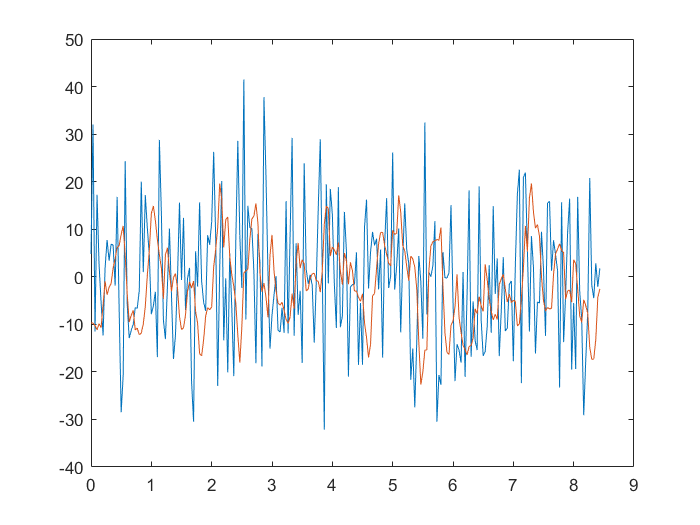

y2=scope.signals(2).values; 

y3=squeeze(y2);
y3=y3.';
constref=80;
y3=y3-constref;

plot(x1,y3); %vermelho - output
hold off 

Preparing for Correlation

Ts=1/30;
y1=y1.';
y3=y3.';
for k=1:241 %every 30 points makes 1sec
    y1_cut(k,1)=y1(k,1);
    y3_cut(k,1)=y3(k,1);
end
data = iddata(y3_cut,y1_cut,Ts);

Calculating CrossCorrelation

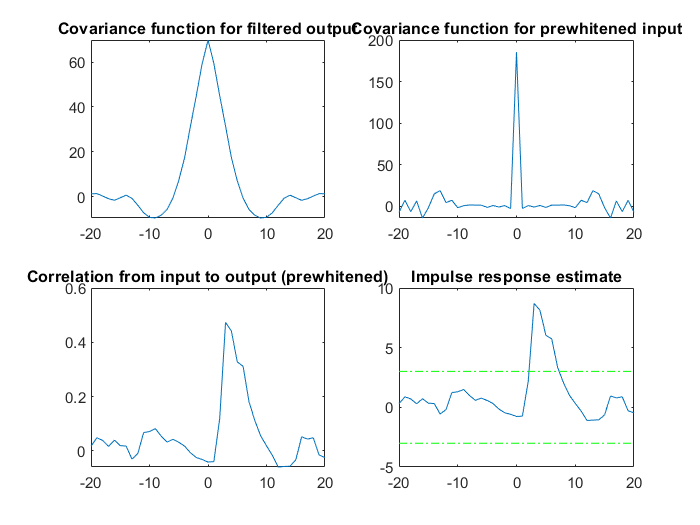

[ir,R,cl] = cra(data,20,10,2);

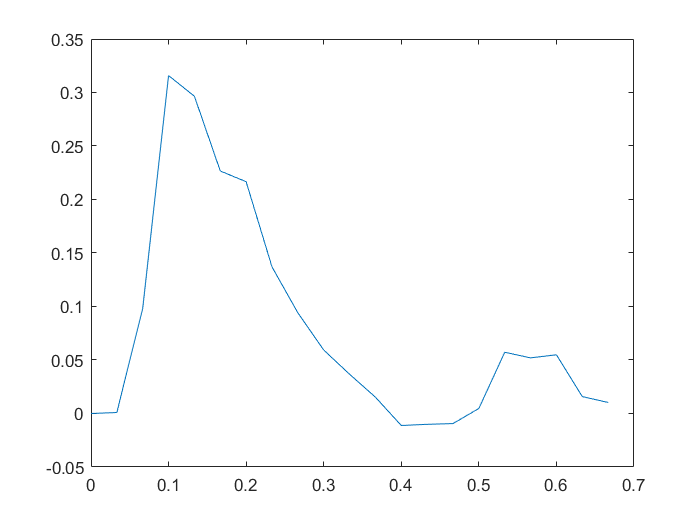


ir_2=ir-ir(1);
% ir_2(2)=[];

for j=1:length(ir_2)
    t_ir(j)=(j-1)/30;
end

figure
plot(t_ir,ir_2)

Obtaining G(z) and G(s)

inputgz=zeros(7,1); %2n+1=9, sistema de 4a ordem
k=1;
for i = 1:2:13
    input_gz_s(k,1)=ir_2(i);
    k=k+1;
end
g_s=input_gz_s;
n=3;
Ts=1/15 %re-sample

Ts = 0.0667


Gz_sto=ir2dtf(g_s,n,Ts)


Gz_sto =
 
    0.09831 z^2 + 0.3651 z + 0.3311
  ------------------------------------
  z^3 + 0.6984 z^2 - 0.9412 z + 0.3423
 
Sample time: 0.066667 seconds
Discrete-time transfer function.



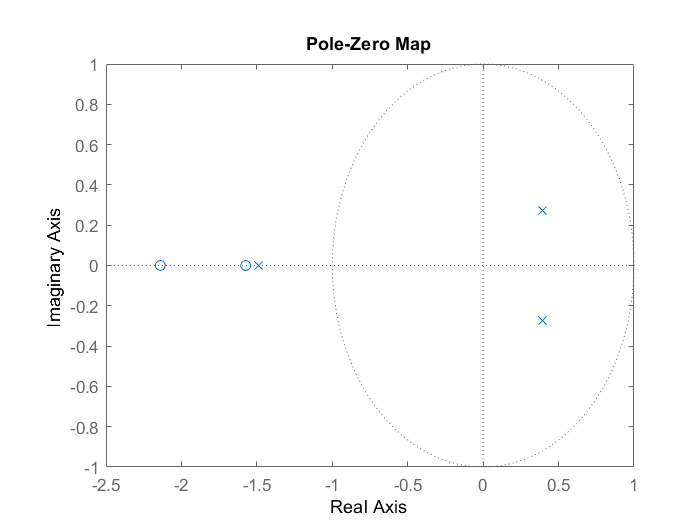

pzmap(Gz_sto)

Gd2d=d2d(Gz_sto,1/30)


Gd2d =
 
  -0.01238 z^3 + 0.1271 z^2 - 0.02027 z + 0.1892
  ----------------------------------------------
  z^4 - 1.322 z^3 + 1.966 z^2 - 1.965 z + 0.7133
 
Sample time: 0.033333 seconds
Discrete-time transfer function.



Gs_s=d2c(Gd2d)


Gs_s =
 
      -3.388 s^3 + 189.1 s^2 - 9359 s + 3.331e05
  --------------------------------------------------
  s^4 + 10.14 s^3 + 2198 s^2 + 4.726e04 s + 4.609e05
 
Continuous-time transfer function.



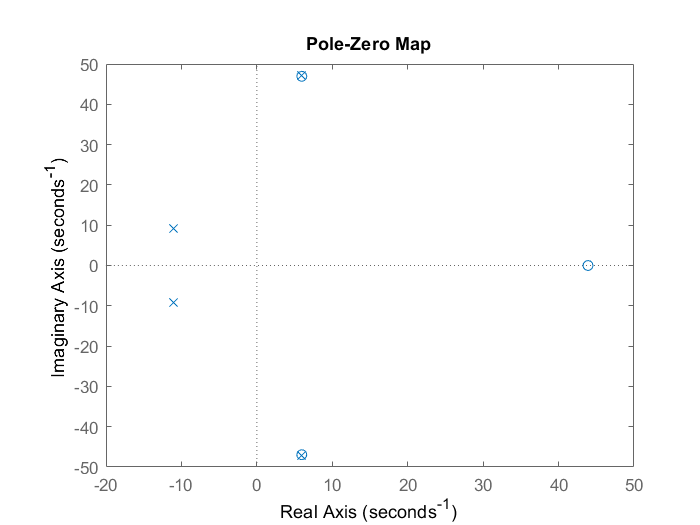


figure
pzmap(Gs_s)

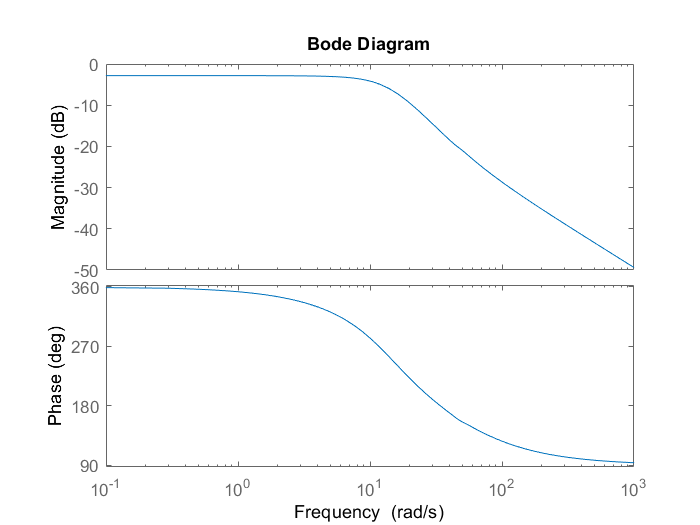

figure
bode(Gs_s)


Gs_s_m=minreal(Gs_s,0.1)


Gs_s_m =
 
    -3.388 s + 148.7
  ---------------------
  s^2 + 22.03 s + 204.3
 
Continuous-time transfer function.



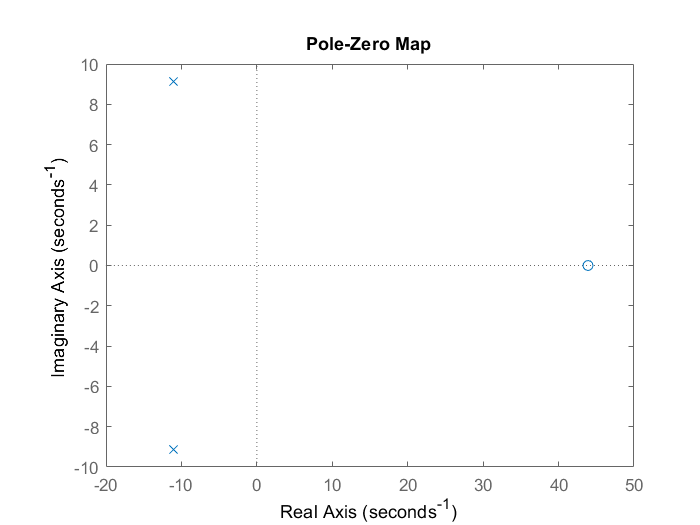

figure
pzmap(Gs_s_m)

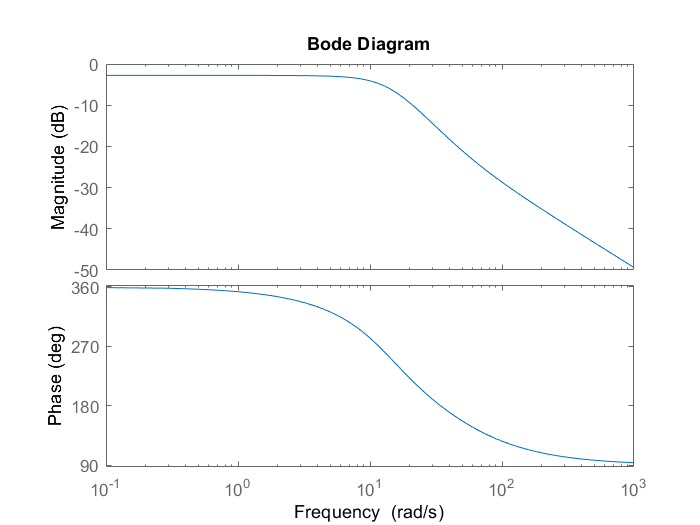

figure
bode(Gs_s_m)


[Gs_sto_final] = modelreducerapp(Gs_s_m)


Gs_sto_final =
 
    -3.388 s + 148.7
  ---------------------
  s^2 + 22.03 s + 204.3
 
Continuous-time transfer function.




figure
pzmap(Gs_sto_final)

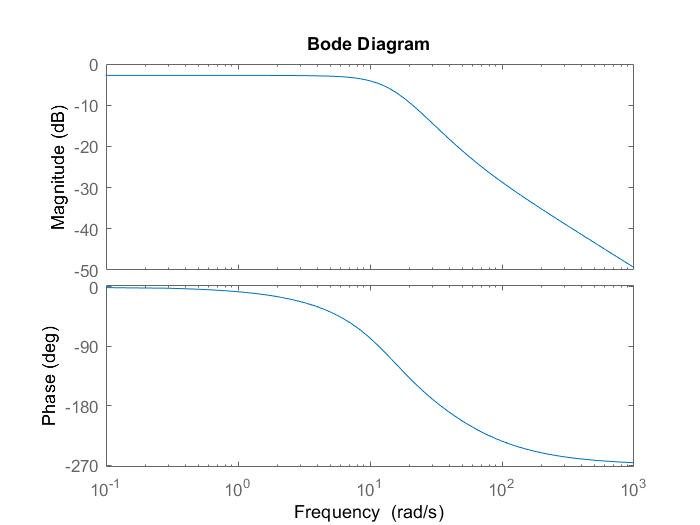

figure
h=bodeplot(Gs_sto_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot

Calculating Fourier Transform

ir_cut=ir_2(1:12); %until deconv impulse response returns to zero
[PHASE,GAIN,W]=fourier_sto(ir_cut);
PHASEdegree=unwrap(PHASE)*180/pi;

Cutting frequencies higher than 30rad/s

W_cut=W(1:38); 
GAIN_cut=GAIN(1:38);
PHASE_cut=PHASEdegree(1:38);

Levy Method

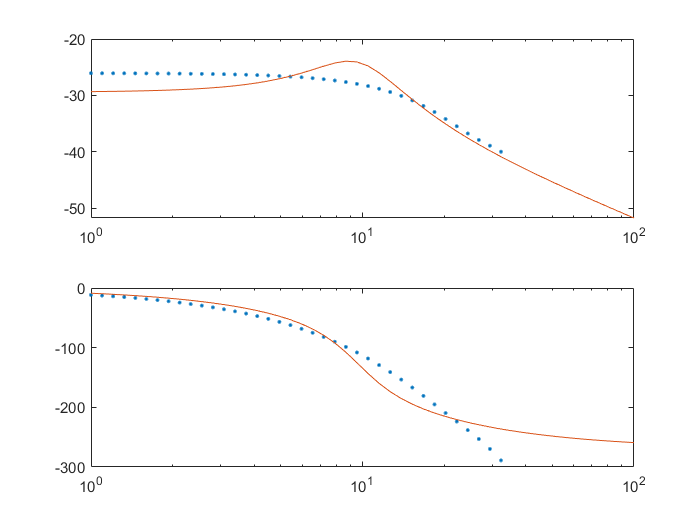

Q.num=[1 0];
Q.den=[2 1 0];
[G_levy_sto, J, handle] = levy_sto (W_cut, GAIN_cut, PHASE_cut, Q, 0);

Gs_levy_sto=tf(G_levy_sto.num,G_levy_sto.den);
Gs_levy_sto=Gs_levy_sto*22 %putting gain back to normal


Gs_levy_sto =
 
      -0.06015 s + 0.7437
  ---------------------------
  0.01068 s^2 + 0.07138 s + 1
 
Continuous-time transfer function.



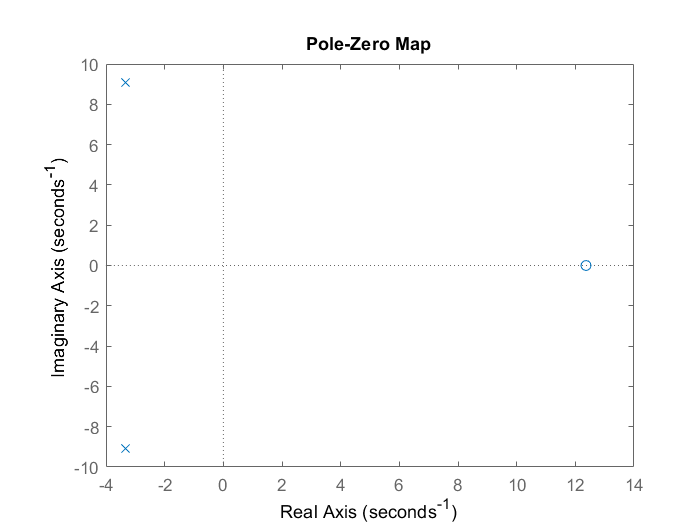


figure
pzmap(Gs_levy_sto)

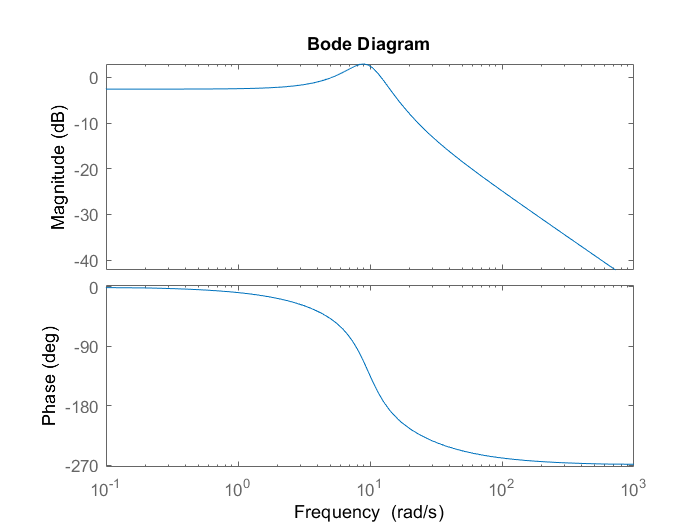

figure
h=bodeplot(Gs_levy_sto);
opt = getoptions(h);%phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot  
hold off

Comparing bode diagrams

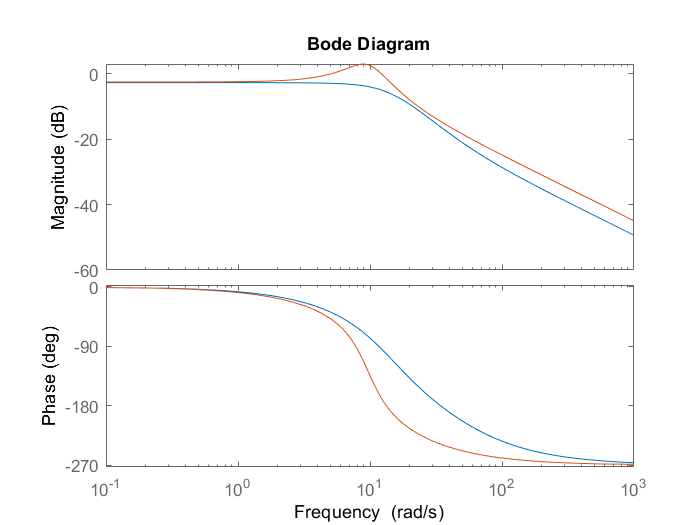

figure
h=bodeplot(Gs_sto_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold on

h=bodeplot(Gs_levy_sto);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot  
hold off

# Sinusoidal Input Comparison

gain_sto=[6.579 -1.1317];
phase_sto=[-35.9580 -111.0029 ];
w_sto=[5.8905 11.7810];

Comparing data

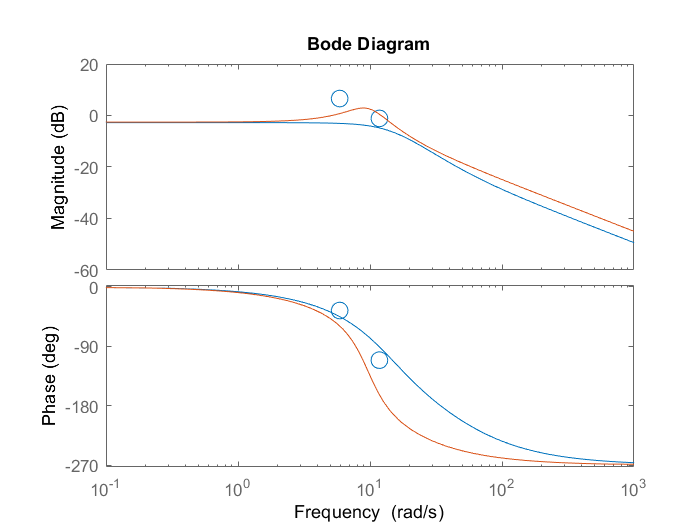

figure
semilogx(w_sto,gain_sto,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_sto_final);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot
hold on


semilogx(w_sto,phase_sto,'o','MarkerSize',10)
hold on

h=bodeplot(Gs_levy_sto);
opt = getoptions(h);  %phase offset correction
opt.PhaseMatching = 'on'; 
opt.PhaseMatchingFreq = 0.1; 
opt.PhaseMatchingValue = 0;
setoptions(h,opt); %update phase plot  
hold off